%clearing
clear;
clc;
close all;

%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

   120    10




cdata1 = cdata(:,:);

returns1 = diff(cdata1) ./ cdata1(1:end-1, :);

returns = returns1(48:107,:);

mu = mean(returns)';
cov_matrix = cov(returns);
num_assets = size(mu, 1);

%PCA section


% doing pca
[coeff, latent, explained] = pcacov(cov_matrix);

%
explained_variance = cumsum(explained);
num_components = find(explained_variance >= 95, 1); %we can change this, varying this allows us to experiment and decide what we can change here, how it affects computation time
disp(num_components);

     8




% dimensionality reduction
coeff_reduced = coeff(:, 1:num_components);
latent_reduced = latent(1:num_components); %check this

% mean is smaller subsace, variance too
%have to project via transpose of the new coeffs
mean_reduced = coeff_reduced' * mu;
cov_reduced = diag(latent_reduced);
%cov_reduced = coeff_reduced' * latent_reduced * coeff_reduced;

% bring back to original space
in_sample_mean_reconstructed = coeff_reduced * mean_reduced;
%to create pxn matrix, multiple x (diagonal)  x(^t)
in_sample_cov_reconstructed = coeff_reduced * cov_reduced * coeff_reduced';

% rf rate for sharpe calculation
rf = 0.00;
shortselltoggle = 0;
% we aim to find the lowest risk possible for each interval between
% returns. Accuracy increases with the more number of portfolios.
target_returns = linspace(min(mu), max(mu), 100);

% Array setup
portfolio_risks = zeros(length(target_returns), 1);
portfolio_returns = zeros(length(target_returns), 1);
portfolio_weights = zeros(length(target_returns), num_assets);

% Solve the optimization problem for each linspaced return
options = optimoptions('quadprog', 'Display', 'off');
for i = 1:length(target_returns)
    target_return = target_returns(i);
    
    % Define the optimization problem
    f = zeros(num_assets, 1); %no constant
    Aeq = ones(1, num_assets); %sum(weights) ==1, we can change this to -1 to 1 to allow for shortselling
    beq = 1;
    A = -in_sample_mean_reconstructed'; % mean return >= target return
    b = -target_return;
    if (shortselltoggle == 0)
        lb = zeros(num_assets, 1);
        ub = ones(num_assets, 1);
    else
        lb = -1 *ones(num_assets, 1);
        ub = ones(num_assets, 1);
    end

    % Solve the quadratic programming problem
    [x, ~, solutionindicator] = quadprog(in_sample_cov_reconstructed, f, A, b, Aeq, beq, lb, ub, [], options);
    
    if solutionindicator == 1 % Solution found
        portfolio_weights(i, :) = x';
        portfolio_returns(i) = in_sample_mean_reconstructed' * x;
        portfolio_risks(i) = sqrt(x' * in_sample_cov_reconstructed * x);
    else
        portfolio_weights(i, :) = NaN;
        portfolio_returns(i) = NaN;
        portfolio_risks(i) = NaN;
    end
end

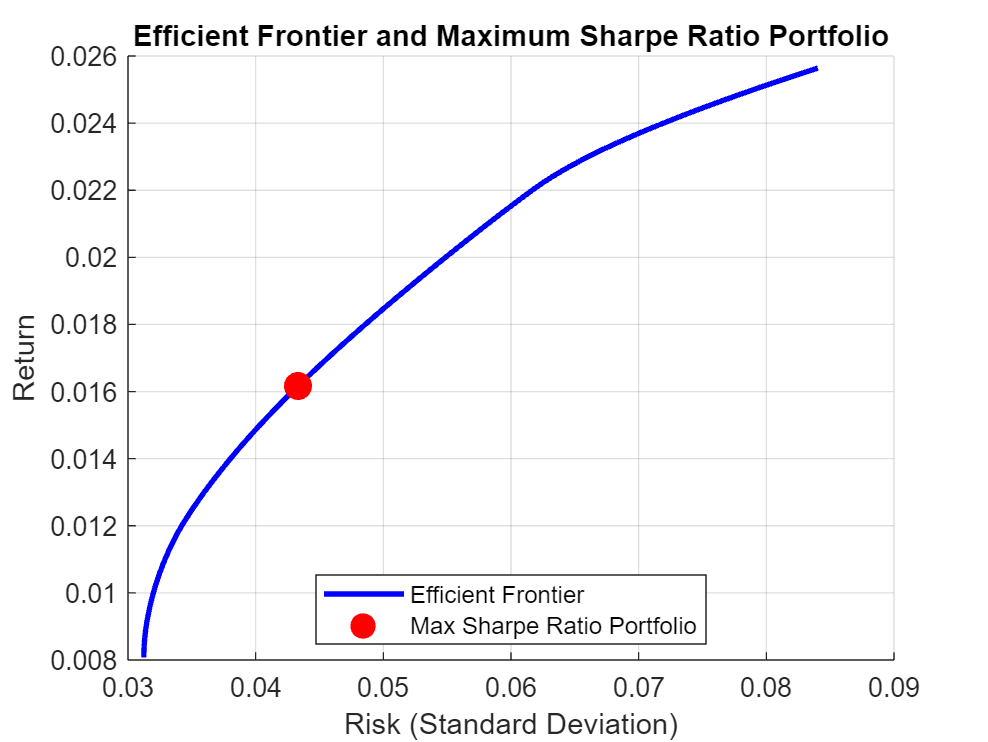


% Remove NaN values
valid_indices = ~isnan(portfolio_returns);
portfolio_risks = portfolio_risks(valid_indices);
portfolio_returns = portfolio_returns(valid_indices);
portfolio_weights = portfolio_weights(valid_indices, :);

%find the sharpe ratios for each generated portfolio
sharpe_ratios = (portfolio_returns - rf) ./ portfolio_risks;

%locate portfolio with max sharpe ratio
[~, sharpehigh] = max(sharpe_ratios);
%return parameters
max_sharpe_weights = portfolio_weights(sharpehigh, :);
max_sharpe_return = portfolio_returns(sharpehigh);
max_sharpe_risk = portfolio_risks(sharpehigh);



%Efficient Frontier plot with risk free rate line (CML)
figure;
hold on;
plot(portfolio_risks, portfolio_returns, 'b-', 'LineWidth', 2);

plot(max_sharpe_risk, max_sharpe_return, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier and Maximum Sharpe Ratio Portfolio');
legend('Efficient Frontier', 'Max Sharpe Ratio Portfolio', 'Location', 'Best');
grid on;


%
disp('weights for the high sharpe ratio portfolio');

weights for the high sharpe ratio portfolio


disp(max_sharpe_weights);

    0.1785    0.3425    0.0726    0.2033    0.0000    0.2030    0.0000    0.0000    0.0000    0.0000




disp(['Maximum Sharpe Ratio: ', num2str(sharpe_ratios(sharpehigh))]);

Maximum Sharpe Ratio: 0.37314


disp(['Expected Portfolio Return: ', num2str(max_sharpe_return)]);

Expected Portfolio Return: 0.016171


disp(['Portfolio Risk (Standard Deviation): ', num2str(max_sharpe_risk)]);

Portfolio Risk (Standard Deviation): 0.043337
